rrAppPath = "C:\Program Files\RoadRunner R2023b\bin\win64";
s = settings;
s.roadrunner.application.InstallationFolder.TemporaryValue = rrAppPath;
rrProj = "C:\Users\colli\Documents\College\MEEN 401 909 Intro to Mech Engr Design\Simulation\Test\Test";

rrApp=roadrunner(rrProj, NoDisplay=true);
%rrApp=roadrunner(rrProj,NoDisplay=false);

openScenario(rrApp,"LeadCutIn3.rrscenario");

rrSim = rrApp.createSimulation

Connection status: 1
Connected to RoadRunner Scenario server on localhost:57249, with client id {acea2111-99b0-4ca9-ada9-e5729c93c316}


rrSim =   ScenarioSimulation with no properties.


hdMap = getMap(rrSim);
lanes = hdMap.map.lanes;


%set(rrSim,"SimulationCommand","Start");
%while strcmp(get(rrSim,"SimulationStatus"),"Running")
%    pause(1);
%end

%rrLog = get(rrSim,"SimulationLog");

%poseActor1 = rrLog.get('Pose','ActorID',1);
%positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
%positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);
%plot(positionActor1_x,positionActor1_y,"r","LineWidth",2)
%
%poseActor2 = rrLog.get('Pose','ActorID',2);
%positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
%positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);
%plot(positionActor2_x,positionActor2_y,"b","LineWidth",2)
%
%title("Agent Positions from RoadRunner Scenario")
%ylabel("Y (m)")
%xlabel("X (m)")

[nodeTable,edgeTable] = helperGetNodesEdges;

graph = navGraph(nodeTable,edgeTable);
%show(graph)

numDestinations = 4

numDestinations = 4

numLanes = height(nodeTable);
% Select random starting node
astart = randi([1 numLanes],1,1);
numLaneNodesStart = height(nodeTable.LanesStruct(astart).Geometry);
bstart = randi([1 numLaneNodesStart],1,1);
xpointstart = nodeTable.LanesStruct(astart).Geometry(bstart,1)

xpointstart = -46.2412

ypointstart = nodeTable.LanesStruct(astart).Geometry(bstart,2)

ypointstart = 44.9332

zpointstart = nodeTable.LanesStruct(astart).Geometry(bstart,3)

zpointstart = 234.1524

start = [xpointstart,ypointstart,zpointstart]

start =   -46.2412   44.9332  234.1524


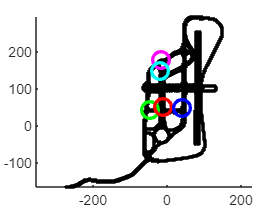

% Select random goal node
% Define four goal positions
goals = zeros(4,3); % Initialize a 4x3 matrix to store goal positions
for i = 1:numDestinations
    agoal = randi([1 numLanes],1,1);
    numLaneNodesGoal = height(nodeTable.LanesStruct(agoal).Geometry);
    bgoal = randi([1 numLaneNodesGoal],1,1);
    xpointgoal = nodeTable.LanesStruct(agoal).Geometry(bgoal,1);
    ypointgoal = nodeTable.LanesStruct(agoal).Geometry(bgoal,2);
    zpointgoal = nodeTable.LanesStruct(agoal).Geometry(bgoal,3);
    goals(i,:) = [xpointgoal, ypointgoal, zpointgoal];
end
%print section
figure
hold on
for i =1:numel(lanes)
    control_points = lanes(i).geometry.values;
    x_coords = arrayfun(@(cp) cp.x,control_points);
    y_coords = arrayfun(@(cp) cp.y,control_points);
    %Z_coords = arrayfun(@(cp) cp.Z,control_points); %Error here
    plot(x_coords,y_coords, 'k.-');
end
plot(xpointstart, ypointstart, 'go', 'MarkerSize', 10, 'LineWidth', 2);

goalColors = ['r', 'b', 'm', 'c'];

for i = 1:numDestinations
    xpointgoal = goals(i, 1);
    ypointgoal = goals(i, 2);
    plot(xpointgoal, ypointgoal, [goalColors(i) 'o'], 'MarkerSize', 10, 'LineWidth', 2);
end

hold off
axis equal

egoStart = strjoin(string(start),",");
setScenarioVariable(rrApp,"EgoInitialPosition",egoStart);
egoStartPosition = getScenarioVariable(rrApp,"EgoInitialPosition");
egoStartPosition = str2double(split(egoStartPosition,","))';

% Storing designated locations
locations(1).name = 'Diagonal Parking';
locations(1).position = [18.3197, 99.348];

locations(2).name = 'Curbside Parking';
locations(2).position = [21.3648, 37.0707];

locations(3).name = 'Parallel Parking';
locations(3).position = [17.6015, 112.127];

locations(4).name = 'Parallel Parking';
locations(4).position = [17.4243, 108.785];

locations(5).name = 'Main St.';
locations(5).position = [17.4243, 108.785];

locations(6).name = 'Liberty St.';
locations(6).position = [16.2964, 44.5729];

locations(7).name = 'State St.';
locations(7).position = [-8.71713, 74.0647];

locations(8).name = 'Pontaic Tr.';
locations(8).position = [-44.7704, 154.126];

locations(9).name = 'Railroad Crossing';
locations(9).position = [-50.553, 71.8247];

locations(10).name = 'Metal Tunnel';
locations(10).position = [-57.2846, 16.6779];

locations(11).name = 'Wolverine Ave.';
locations(11).position = [49.8527, 53.1169];

locations(12).name = 'Carrier & Gabble Dr.';
locations(12).position = [71.4524, 184.41];

locations(13).name = 'Vine Tunnel';
locations(13).position = [21.01, 144.815];

%make a bike lane node and see what it does when it goes there

%Getting a random location
index = randi(length(locations));
randomLocation = locations(index);
disp(randomLocation);

        name: 'Liberty St.'
    position: [16.2964 44.5729]




numDestinations = 4;

% Define four random locations
randomLocations = zeros(numDestinations, 2); % Initialize a 4x2 matrix to store locations
selectedLocations = cell(numDestinations, 1); % To store names of selected locations

for i = 1:numDestinations
    index = randi(length(locations));
    randomLocations(i, :) = locations(index).position;
    selectedLocations{i} = locations(index).name;
end

% Print section
figure
hold on

for i =1:numel(lanes)
    control_points = lanes(i).geometry.values;
    x_coords = arrayfun(@(cp) cp.x,control_points);
    y_coords = arrayfun(@(cp) cp.y,control_points);
    plot(x_coords,y_coords, 'k.-');
end
%plot(xpointstart, ypointstart, 'go', 'MarkerSize', 10, 'LineWidth', 2);

% Plot start location (choose one random location as starting point)
startLocationIndex = randi(length(locations));
startLocation = locations(startLocationIndex).position;
startLocationName = locations(startLocationIndex).name;
plot(startLocation(1), startLocation(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);

% Display starting location
disp(['Starting at ' startLocationName]);

Starting at State St.



% Plot goal locations
goalColors = ['r', 'b', 'm', 'c'];
for i = 1:numDestinations
    plot(randomLocations(i, 1), randomLocations(i, 2), [goalColors(i) 'o'], 'MarkerSize', 10, 'LineWidth', 2);
    % Display each destination
    disp(['Destination ' num2str(i) ': ' selectedLocations{i}]);
    goals(i,:) = [randomLocations(i, 1), randomLocations(i, 2), 0]; %updating the goals for the finder
end

Destination 1: Main St.
Destination 2: Metal Tunnel
Destination 3: Wolverine Ave.
Destination 4: Parallel Parking


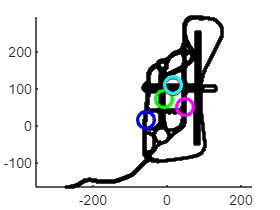


hold off
axis equal

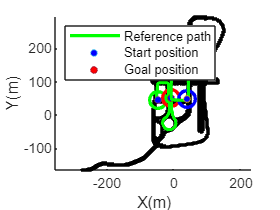

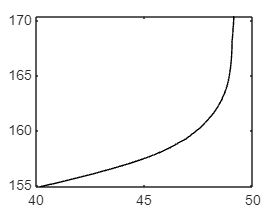



planner = plannerAStar(graph);
for i = 1:numDestinations
    goal = goals(i,:);

    % Convert goal position to string for scenario variable
    egoGoal = strjoin(string(goal),",");
    setScenarioVariable(rrApp,"Goal",egoGoal);
    egoGoalPosition = getScenarioVariable(rrApp,"Goal");
    egoGoalPosition = str2double(split(egoGoalPosition,","))';

    try
        % Plan path
        refPath = HelperPlanPath.planPath(planner, graph, start, goal);

        % Plotting the path and markers...
        pRefPath = plot(refPath(:,1), refPath(:,2), 'Color', "g", 'LineWidth', 2);
        pStart = plot(start(1), start(2), "o", 'MarkerFaceColor', "b", 'MarkerSize', 4);
        pEnd = plot(goal(1), goal(2), "o", 'MarkerFaceColor', "r", 'MarkerSize', 4);
        legend([pRefPath, pStart, pEnd], {"Reference path", "Start position", "Goal position"}, 'Location', "northwest");

    catch ME
        fprintf('Error planning path to goal: [%f, %f]\n', goal(1), goal(2));
        fprintf('Error message: %s\n', ME.message);
        % Optionally, display more detailed error information
        fprintf('Error identifier: %s\n', ME.identifier);
        fprintf('Error stack trace:\n');
        disp(ME.stack);
    end

    % Update start position for the next iteration
    start = goal;
end

set(rrSim,SimulationCommand="Start")
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(0.01)
end

setScenarioVariable(rrApp,ChangeSpeed_TargetSpeed="18")

obstacleDistance = 50;
setScenarioVariable(rrApp,ReplanTriggerDistance=num2str(obstacleDistance));
setScenarioVariable(rrApp,ObstacleDistance=num2str(obstacleDistance));